R = 100;
C = 10e-6;

zeta = 0.1;
L = R^2*C/(4*zeta^2) 

L = 2.5000

s = tf('s');
T = 1/(L*C*s^2+R*C*s+1)

T =
 
              1
  -------------------------
  2.5e-05 s^2 + 0.001 s + 1
 
Continuous-time transfer function.



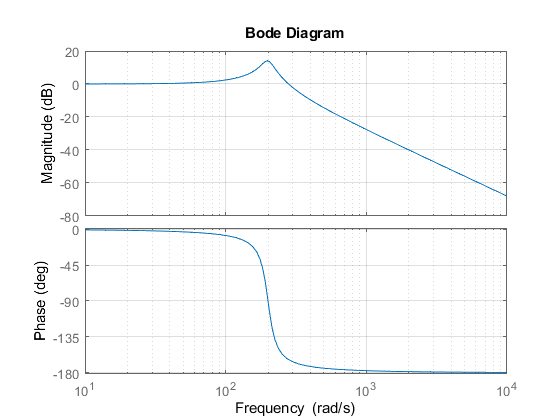

bode(T)
grid on

w = 1/sqrt(L*C)

w = 200

[mag1,phase1] = bode(T,w/10)

mag1 = 1.0099

phase1 = -1.1573

[mag2,phase2] = bode(T,w)

mag2 = 5.0000

phase2 = -90.0000

[mag3,phase3] = bode(T,w*10)

mag3 = 0.0101

phase3 = -178.8427

wd = (1-zeta^2)*w;
[mag4,phase4] = bode(T,wd)

mag4 = 5.0252

phase4 = -84.2608

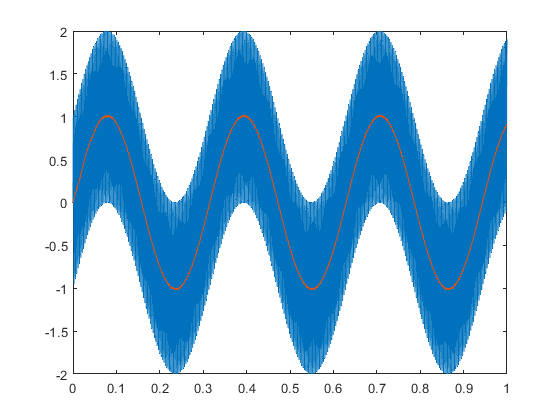

out = sim('Week13c_simulink.slx');

u = out.u;
v = out.v;
t = out.tout;

plot(t,u,t,v)